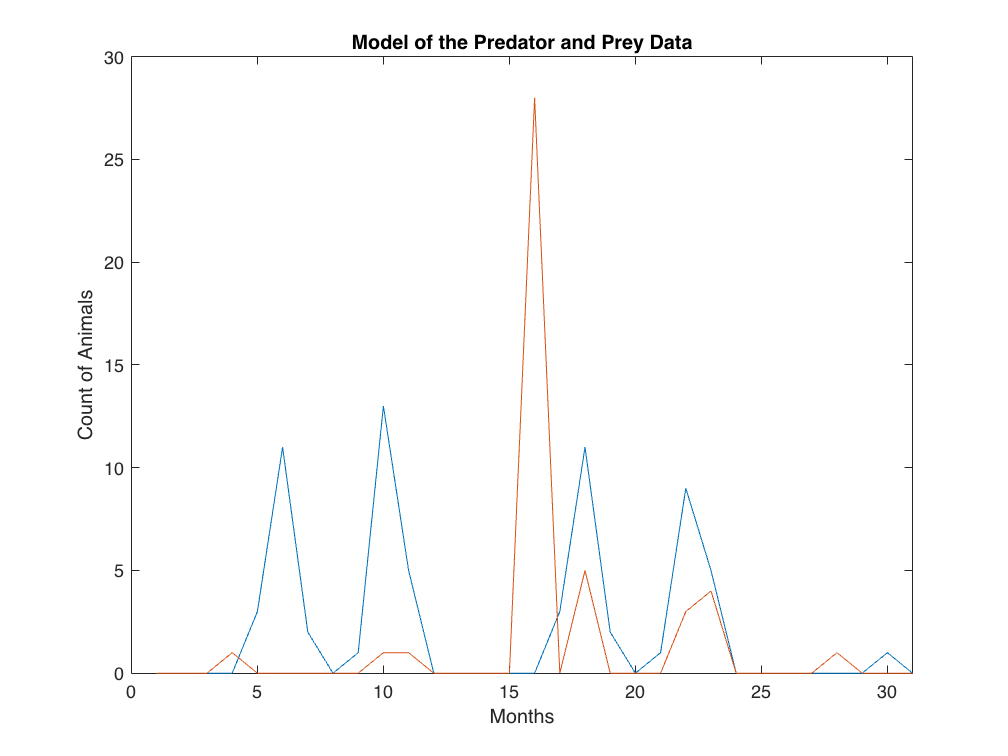


% Reading in lion data from excel file
lion_data = readtable('wildcam-21apr2022_Lion.xlsx');


% Reading in wildebeest data from excel file
wb_data = readtable('wildcam-21apr2022_WB.xlsx');


% Getting only the wildebeest data we need
wb_month = lower(convertCharsToStrings(wb_data.month));
wb_years = wb_data.year; 
wb_count = wb_data.species_count;


% Now for lions
lion_months = lower(convertCharsToStrings(lion_data.month));
lion_years = lion_data.year;
lion_count = lion_data.species_count;


% Finding count per month of animals in different years
count_per_m_2013_l = count_per_m(lion_months, lion_years, 2013);
count_per_m_2014_l = count_per_m(lion_months, lion_years, 2014);
count_per_m_2015_l = count_per_m(lion_months, lion_years, 2015);
count_per_m_2013_wb = count_per_m(wb_month, wb_years, 2013);
count_per_m_2014_wb = count_per_m(wb_month, wb_years, 2014);
count_per_m_2015_wb = count_per_m(wb_month, wb_years, 2015);


% Joining all of the years together
count_per_m_l = [count_per_m_2013_l count_per_m_2014_l count_per_m_2015_l];
count_per_m_wb = [count_per_m_2013_wb count_per_m_2014_wb count_per_m_2015_wb];


% Defining our interval of data collection
time = 1:36;


% Plotting the data
plot(time, count_per_m_l, time, count_per_m_wb)
xlim([0 31])
xlabel('Months'); ylabel('Count of Animals');
title('Model of the Predator and Prey Data');



% Fitting the data using interpolation
pre_lion_fitted = griddedInterpolant(time, count_per_m_l,'cubic');
lion_count_fitted = pre_lion_fitted(time);

pre_wb_fitted = griddedInterpolant(time, count_per_m_wb, 'cubic');
wb_count_fitted = pre_wb_fitted(time);





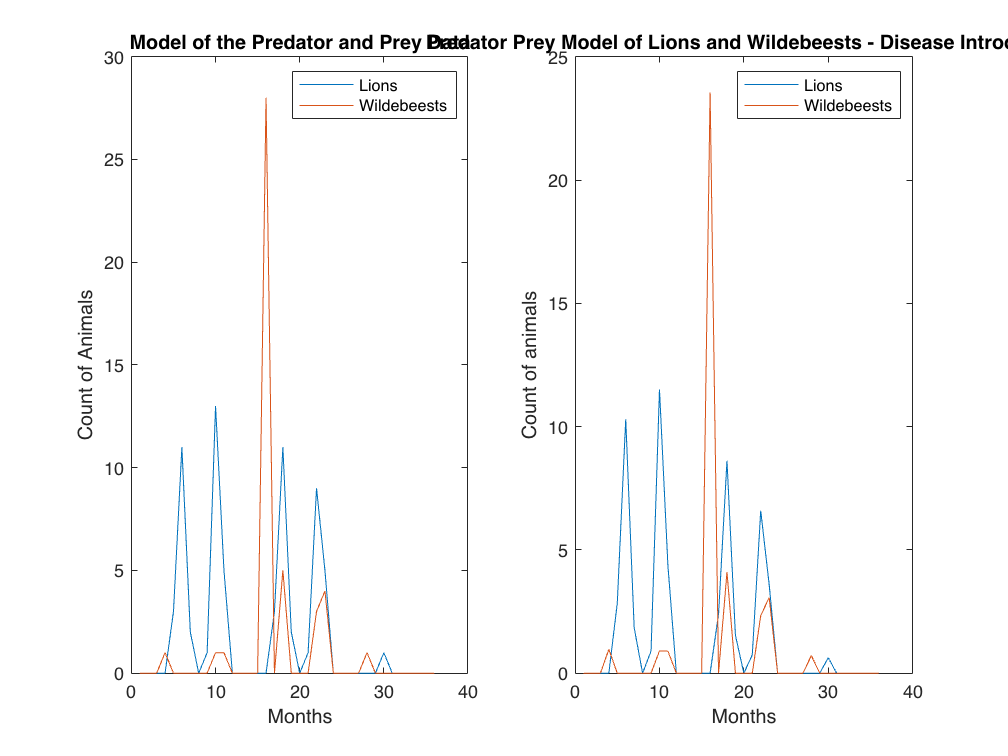


% Requesting the user to make inputs now, making sure to display an error
% message if they do something wrong
month1_input = input("What month would you like to start your simulation from? (Enter a number, 1-35) ");
if month1_input <1 || month1_input >35
    error('Enter a month number between 1 and 35')
elseif isa(month1_input, 'double') == 0
    error('Enter an integer for month number between 1 and 35')
end

month2_input = input("What month would you like to end your simulation at? (Enter a number after the starting month to 36) ");
if month2_input < month1_input || month2_input >36
    error('Enter a month number between your first month and 36')
elseif isa(month2_input, 'double') == 0
    error('Enter an integer for month number between 1 and 36')
end

wb_input = input('How many wildebeests would you like to simulate? (Enter a number) ');
if isa(wb_input, 'double') == 0
    error('Please enter an integer for the number of wildebeests.')
end

l_input = input('How many lions would you like to simulate? (Enter a number) ');
if isa(wb_input, 'double') == 0
    error('Please enter an integer for the number of lions.')
end

disease_input = lower(input('Would you like to simulate the effects of a disease? (y/n)', "s"));
if disease_input ~= 'y' & disease_input ~= 'n'
    error('Disease input needs to be "y" or "n". Please try again')
end

time_input = month1_input:month2_input;


figure;
subplot(1,2,1)
plot(time, count_per_m_l, time, count_per_m_wb)
xlabel('Months'); ylabel('Count of Animals');
title('Model of the Predator and Prey Data');
legend('Lions', 'Wildebeests')


if disease_input == 'y'

    % Using an SIR model to manipulate the fitted equations
    [t_2, y_2] = ode45('SIRD_pred_prey', [month1_input month2_input], [wb_input 2 0 0]);
    [t_3, y_3] = ode45('SIRD_pred_prey', [month1_input month2_input], [l_input 2 0 0]);
    
    s_wb = y_2(:,1);
    i_wb = y_2(:,2);
    r_wb = y_2(:,3);
    d_wb = y_2(:,4);
    
    s_l = y_3(:,1);
    i_l = y_3(:,2);
    r_l = y_3(:,3);
    d_l = y_3(:,4);
    
    
    % Find ratio of dead wildebeest to ones left in the population
    wb_ratio_sird = d_wb./(s_wb + i_wb + r_wb);
    wb_ratio_sird = linspace(wb_ratio_sird(1),wb_ratio_sird(end), 36);
    
    
    % Doing the same for lions
    l_ratio_sird = d_l./(s_l + i_l + r_l);
    l_ratio_sird = linspace(l_ratio_sird(1),l_ratio_sird(end), 36);
    
    
    % Killing off some of the population, using this to replace regular
    % population
    for idx = 1:length(lion_count_fitted)
        if lion_count_fitted(idx) ~= 0
            lion_count_fitted(idx) = lion_count_fitted(idx).*(1-l_ratio_sird(idx));
        end
    end
    
    for idx = 1:length(wb_count_fitted)
        if wb_count_fitted(idx) ~= 0
            wb_count_fitted(idx) = wb_count_fitted(idx).*(1-wb_ratio_sird(idx));
        end
    end

    % Plotting the data
    subplot(1,2,2)
    plot(time_input, lion_count_fitted(time_input), time_input, wb_count_fitted(time_input))
    xlabel('Months'); ylabel('Count of animals'); 
    title('Predator Prey Model of Lions and Wildebeests - Disease Introduced');
    legend('Lions', 'Wildebeests')

elseif disease_input == 'n'
    % Plotting an ideal population
    [t_ideal, y_ideal] = ode45('pred_prey', [month1_input month2_input], [wb_input l_input]);   
    y1_ideal = y_ideal(:,1);
    y2_ideal = y_ideal(:,2);
    subplot(1,2,2)
    plot(t_ideal, y1_ideal, t_ideal, y2_ideal)
    xlabel('Months'); ylabel('Count of animals'); 
    title('Predator Prey Model of Lions and Wildebeests - No Disease');
    legend('Wildebeests', 'Lions')



end

% Displaying the functions used
type count_per_m.mlx

function count_per_m_yr = count_per_m(data_animal_month, animal_years, target_yr)

count_yr = 0;

for yr_idx = 1:length(animal_years) 
    if animal_years(yr_idx) == target_yr
        count_yr = count_yr + 1;
    end
end

animal_sighted_mnths = cell(1, count_yr);

k = 1;
for yr_idx = 1:length(animal_years)
    animal_sighted_mnths(k) = {data_animal_month(yr_idx)};
    k = k+1;
    if k > count_yr
        break
    end
end

animal_sighted_mnths = string(animal_sighted_mnths);

months_in_yr = ["jan"; "feb"; "mar"; "apr"; "may"; "jun"; "jul"; "aug"; "sep"; "oct"; "nov"; "dec"];
vector_zeros_mnths = zeros(1,length(months_in_yr));
count_per_m_yr = vector_zeros_mnths;

for i = 1:length(animal_sighted_mnths)
    switch animal_sighted_mnths(i)
        case 'jan'
            count_per_m_yr(1) = count_per_m_yr(1) + 1;
        case 'feb'
            count_per_m_yr(2) = count_per_m_yr(2) + 1;
        case 'mar'
            count_per_m_yr(3) = count_per_m_yr(3) + 1;
        case 'apr'
            c

type SIRD_pred_prey.mlx

function ydot_dot = SIRD_pred_prey(t, y)

beta = 0.005;
nu = 0.05;

s = y(1);
i = y(2);
r = y(3);
d = y(4);

dSdt = -beta*s*i;
dIdt = beta*s*i - nu*i;
dRdt = nu*i/2;
dead = nu*i/2;

ydot_dot = [dSdt; dIdt; dRdt; dead];

end


type pred_prey.mlx

function ydot = pred_prey(t, y)

a = 3;
b = 2;
c = 1.5;
d = 2;


y1 = y(1);
y2 = y(2);

ydot1 = a*y1 - b*y1*y2;
ydot2 = -c*y2 + d*y1*y2;

ydot = [ydot1; ydot2];


end
